# Behavioral analysis of multi-reard experiment on 12/21/2023

## Experiment infomation

Recording data: 12/20/2024

Number of sessions: 4

Reward flavior: pear and banana

%% Experiment info
n_session = 2;
n_feeder = 4;
reward_list = {"banana","grape"};
n_flavior = length(reward_list);
reward_session = [1,2,0,0; 2,1,0,0]; % row = session, col = flavor. number is corresponding to the flavor in reward_flavor. 0 = no flavor is allocated.

## Data structure

cortex: reward and TTL signals

cdp: bat position and acceleration

reward: feeder landing

camera: camera recordings

analysis: directory to save all outputs of analysis

Serial_numbers.txt: serial number of tags

%% Directory
data_dir = pwd;
fprintf('Data directory is %s',pwd)

Data directory is Z:\users\Tatsumi\data\MultiReward\recording\groupC\231221

% cortex
cortex_dir  =   dir(fullfile(data_dir,'cortex','*c3d'));
cortex_file =   fullfile(cortex_dir.folder,cortex_dir.name);
% reward
reward_dir  =   dir(fullfile(data_dir,'reward','*.mat'));
% cdp
cdp_dir     =   dir(fullfile(data_dir,'cdp','*cdp*.txt'));
cdp_file    =   fullfile(cdp_dir.folder,cdp_dir.name);
% serial number
serial_dir  =   dir(fullfile(data_dir,'*Serial_numbers*'));
serial_file =   fullfile(serial_dir.folder,serial_dir.name);
% analysis
res_dir_path     =   fullfile(data_dir,'analysis');
if isempty(dir(res_dir_path))
    mkdir(res_dir_path)
end
% Figure
fig_dir_path    =   fullfile(res_dir_path,'figure');
if isempty(dir(fig_dir_path))
    mkdir(fig_dir_path)
end

## Preprocessing

### Preprocess raw tag data

Extract the tag data from the raw cdp data by the *ExtractCdp* function. *sync_data(:,8)* is the timestamps interpolated based on the pseudo-Fibonacci TTLs. In this time vector, t=0 is the timing of the 1st pulse of the pseudo-Fibonacci TTLs. Make sure that this time vector will be shifted for 1.05 sec to set t=0 as the 1st pulse of the 3-sec TTLs.

% Preprocess raw cdp data
cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*')); % raw cdp data
serial_number   =   load(serial_file); serial_number   =   serial_number'; % serial number of tags
if isempty(cdp_extracted)
    cd(cdp_dir.folder)
    ExtractCdp_AF_TY_v2('cdp',res_dir_path,0,'Include',serial_number) % Extract cdp data keeping the tag order
    cd(data_dir)
    % Load data
    cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*'));
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
elseif length(cdp_extracted) == 1
    disp('Extracted data are found in the directory.')
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
else
    error('Multiple files with the specified name were found. Check the file name.')
end

                 Fs: 100
             tag_SN: [10×1 double]
            sync_SN: 17040920
               sync: 1
      sync_duration: 77.6929
       sync_samples: 466136
       tag_duration: [77.6928 77.6928 77.6928 77.6928 77.6928 77.6928 77.6926 77.6928 77.6928 77.6928]
        tag_samples: [464107 464250 464090 464105 464081 464078 464073 464298 464275 463995]
    tag_ac_duration: [77.6928 77.6927 77.6928 77.6926 77.6927 77.6929 77.6929 77.6929 77.6927 77.6928]
     tag_ac_samples: [464142 463777 469085 467012 468777 470603 467473 467972 470094 466532]
               tags: 10



Sync: Fs (network time VS interpolated): 100Hz VS 100 Hz


Pos Tag1: Fs (network time VS interpolated): 99.56 Hz VS 99.56 Hz
Pos Tag2: Fs (network time VS interpolated): 99.59 Hz VS 99.59 Hz
Pos Tag3: Fs (network time VS interpolated): 99.56 Hz VS 99.56 Hz
Pos Tag4: Fs (network time VS interpolated): 99.56 Hz VS 99.56 Hz
Pos Tag5: Fs (network time VS interpolated): 99.55 Hz VS 99.55 Hz
Pos Tag6: Fs (network time VS interpolated): 99.55 Hz VS 99.55 Hz
Pos Tag7: Fs (network time VS interpolated): 99.55 Hz VS 99.55 Hz
Pos Tag8: Fs (network time VS interpolated): 99.6 Hz VS 99.6 Hz
Pos Tag9: Fs (network time VS interpolated): 99.6 Hz VS 99.6 Hz
Pos Tag10: Fs (network time VS interpolated): 99.54 Hz VS 99.54 Hz


Acc Tag1: Fs (network time VS interpolated): 99.57 Hz VS 99.57 Hz
Acc Tag2: Fs (network time VS interpolated): 99.49 Hz VS 99.49 Hz
Acc Tag3: Fs (network time VS interpolated): 100.6 Hz VS 100.6 Hz
Acc Tag4: Fs (network time VS interpolated): 100.2 Hz VS 100.2 Hz
Acc Tag5: Fs (network time VS interpolated): 100.6 Hz VS 100.6 Hz
Acc Tag6: Fs (network time VS interpolated): 101 Hz VS 101 Hz
Acc Tag7: Fs (network time VS interpolated): 100.3 Hz VS 100.3 Hz
Acc Tag8: Fs (network time VS interpolated): 100.4 Hz VS 100.4 Hz
Acc Tag9: Fs (network time VS interpolated): 100.8 Hz VS 100.8 Hz
Acc Tag10: Fs (network time VS interpolated): 100.1 Hz VS 100.1 Hz


Output file is *extracted_YYMMDD_cdp_*.mat* under the "analysis" directory.

### Extract behavior data

The *Process_extracted_cdp* function extract behavioral features from the preprocessed data. The output is *Extracted_Behavior_YYMMDD.mat* under the "Ext_Behavior_YYMMDD_HHMM.mat" directory.

The variable *t* in the output file is the time vector for global time. The global time is set so that t=0 is the timing of the 1st 3-sec TTLs.

% Extract behaviors
beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
if isempty(beh_dir)
    cd(res_dir_path)
    Process_extracted_cdp_TY_v0() % Extract behavioral features
    cd(data_dir)
    % Load data
    beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
    load(fullfile(beh_dir.folder,beh_dir.name))
elseif length(cdp_extracted) == 1
    disp('Behavior data are found in the directory.')
    load(fullfile(beh_dir.folder,beh_dir.name))
    disp('Behavior data are loaded.')
else
    error('Multiple files were contained in the directory. Check the file name.')
end

...Processing Ciholas Data...


### Extract feeder data

The information related to reward provision is stored in the MATLAB files in the reward directory. These files contain the timings of reward provision, the identity of the bat who landed on feeders, the identity of feeders, etc.

#### Extracting sync signals

Extract the sync and reward information from the c3d file and save them into a MATLAB file.

% Extract synchronization and reward signals from c3d file
analog_dir = dir(fullfile(cortex_dir.folder,'analog_signal.mat'));
if isempty(analog_dir)
    [~,~,AnalogSignals,AnalogFrameRate,~,~,~] = readC3D_analog(cortex_file); % read C3D data. Column 1 = reward, Column 2 = TTL, Column 3 = CDP server
    save(fullfile(cortex_dir.folder,'analog_signal.mat'),'AnalogSignals','AnalogFrameRate')
elseif length(analog_dir)==1
    disp('Analog signal data are found and loaded.')
    load(fullfile(analog_dir.folder,analog_dir.name))
else
    error('Multiple files were contained in the directory. Check the file name.')
end

Analog signal data are found and loaded.


Then assign the global timestamps based on the 3-sec TTLs. Make sure that t=0 is at the 1st 3-sec TTL.

% % Align time based on the pseudo-Fibonacci TTLs
% sync_3sec  =   AnalogSignals(:,2);
% cortex_time     =   (1:length(sync_3sec))'/AnalogFrameRate; % time points by the cortex
% % Detect cortex times corresponding to peaks in the sync signal separated by at least 2s
% % [~, TTL_cortex_times] = findpeaks(normalize(sync_fibonacci,'zscore'),cortex_time,'MinPeakHeight',1,'MinPeakDistance',2);
% % Detect network times corresponding to crossing 90% reference level in the sync signal
% [~,~,TTL_cortex_times] =   risetime(normalize(sync_3sec,'zscore'),cortex_time);
% if length(TTL_cortex_times)==length(true_TTL) % This part should be omitted in the future so that processing the reward data does not depend on the cdp data.
%     TTL_cortex_times    =   TTL_cortex_times(true_TTL); % Avoid artifacts by turning the Master-9 off
% end
% rec_duration = 10800;   %approx rec duration (s), 10800 covers 3 hours
% TTL_abs_times = [0; cumsum(repmat(3,rec_duration*2,1))];
% TTL_abs_times = TTL_abs_times(1:length(TTL_cortex_times));
% 
% cortex_t = interp1(TTL_cortex_times,TTL_abs_times,cortex_time,'linear','extrap');   % interpolation of time based on the TTL signals
% AnalogSignals(:,4)  =   cortex_t;

The global timestamp can be made based on the pseudo-Fibonacci TTLs. In that case, the time vector should be shifted for 1.05 sec to make sure that t=0 is at the 1st 3-sec TTL.

Note: use the pseudo-Fibonacci TTLs for now instead of the 3sec TTLs because the pseudo-Fibonacci TTLs are used for processing the cdp data.

% Align time based on the pseudo-Fibonacci TTLs
sync_fibonacci  =   AnalogSignals(:,3);
cortex_time     =   (1:length(sync_fibonacci))'/AnalogFrameRate; % time points by the cortex

% Align analog signals to the global timestamps
% Detect cortex times corresponding to peaks in the sync signal separated by at least 2s
% [~, TTL_cortex_times] = findpeaks(normalize(sync_fibonacci,'zscore'),cortex_time,'MinPeakHeight',1,'MinPeakDistance',2);
% Detect network times corresponding to crossing 10% reference level in the sync signal
[~,~,TTL_cortex_times] =   risetime(normalize(sync_fibonacci,'zscore'),cortex_time);

% Identify artifacts
[~, ~, TTL_width, ~] = findpeaks(normalize(sync_fibonacci,'zscore'),cortex_time, ...
    'MinPeakHeight',1,'MinPeakDistance',2);
med_cdp =   median(TTL_width);
mad_cdp =   mad(TTL_width,1);
true_TTL2    =   ~(TTL_width<med_cdp - 5*mad_cdp);

if sum(true_TTL2) ~= sum(true_TTL) | length(true_TTL2)~=length(true_TTL)
    disp('Mismatch of artifact detection between cdp and cortex.')
    if length(TTL_cortex_times) == length(true_TTL)
        TTL_cortex_times = TTL_cortex_times(true_TTL);
    end
else
    if length(TTL_cortex_times) == length(true_TTL)
        TTL_cortex_times = TTL_cortex_times(true_TTL2);
    end
end

Unrecognized function or variable 'true_TTL'.


rec_duration = 10800;   %approx rec duration (s), 10800 covers 3 hours
TTL_time_diff = [21; 13; 8; 5; 4];  %TTL delays in s
TTL_abs_times = [0; cumsum(repmat(TTL_time_diff,round(rec_duration*2/sum(TTL_time_diff)),1))];
TTL_abs_times = TTL_abs_times(1:length(TTL_cortex_times));

cortex_t2 = interp1(TTL_cortex_times,TTL_abs_times,cortex_time,'linear','extrap');   % interpolation of time based on the TTL signals
cortex_t2 = cortex_t2 + 1.05; % Shift the time vector for 1.05 sec
AnalogSignals(:,4)  =   cortex_t2;

Make some figures to show the time alignment.

figure
set(gcf, 'units','normalized','outerposition',[0 0.05 1 0.9]);
tiledlayout(3,5,"TileSpacing","tight")
t_titles = {"Reward","3-sec TTLs","pseudo-Fibonacci TTLs"};
for i=1:3
    nexttile([1,4])
    plot(AnalogSignals(:,4),AnalogSignals(:,i))
    title(t_titles(1))
    xlabel('Time (sec)')
    ylabel('Amplitude')
    ylim([-1,5])

    nexttile([1,1]);
    plot(AnalogSignals(AnalogSignals(:,4)>-5 & AnalogSignals(:,4)<20,4),AnalogSignals(AnalogSignals(:,4)>-5 & AnalogSignals(:,4)<20,i))
    ylim([-1,5])
    xlim([-5,20])
end
saveas(gcf,fullfile(fig_dir_path,'AnalogSignals.png'))

#### Aligning the reward signals to the global time

Reward data for each session have timestamps based on their local time, so they should be concatenated and assigned with the global timestamps. Also, add some columns to the output data.

% concatenate all reward signals.
reward = [];
for dd = 1:length(reward_dir)
    load(fullfile(reward_dir(dd).folder,reward_dir(dd).name),'bhv_data')
    n_trials = size(bhv_data.trials,1);
    reward_field      =   bhv_data.fields(9:13);
    reward_field{1} = 'bat_ID';
    reward_field{6} = 'session';
    reward_to_add  =   [bhv_data.trials(:,9:13),repmat(dd,n_trials,1)]; % Session idx
    reward = [reward;reward_to_add];
end

% Add information to reward data table
for trial = 1:size(reward,1)
    feeder  =   reward(trial,ismember(reward_field,'activated_feeder'));
    session =   reward(trial,ismember(reward_field,'session'));
    reward(trial,7) = reward_session(session,feeder);
end
reward_field{7} = 'reward_type';

Then compare the timings of reward provision between the Cortex and the reward data. In this block, compare the number of detected peaks by two different functions, *findpeaks* and *risetime*, to find the optimal parameter for *findpeaks* function. The *findpeaks* function is good in terms of that it returns the peak timings based on the given time vector, but the peak detection depends on its parameter. On the other hand, *risetime* robustly detect all peaks, but its output is interpolated values. So, the parameter for *findpeaks* is optimized by comparing the number of detected peaks between two different functions.

% Detect the reward signals recorded in the cortex system. Notice that non-reward landings were not detected.
minpeakdistance = 1; % Initial value for the minimum peak distance. Decrease this value until all the peaks are detected
all_peak_detected = false; % The flag if all the peaks are detected.
while ~all_peak_detected
    [~, reward_times,w_reward_signal,~] = findpeaks(normalize(AnalogSignals(:,1),'zscore'),AnalogSignals(:,4),'MinPeakHeight',3,'MinPeakDistance',minpeakdistance); % Detection by findpeaks
    [~, reward_times2,~] =   risetime(normalize(AnalogSignals(:,1),'zscore'),AnalogSignals(:,4)); % detection by risetime
    % Validate the detection by comparing the # of detected peaks by two
    % different methods
    if length(reward_times) ~= length(reward_times2)
        minpeakdistance = minpeakdistance - 0.1; % Decrease the threshold by 0.1
    else
        fprintf('Final MinPeakDistance was %.1f \n',minpeakdistance)
        fprintf('%d peaks were detected. \n',length(reward_times))
        all_peak_detected = true;
    end
end

Final MinPeakDistance was 0.5 


238 peaks were detected. 


There are false pulses at the start of each session. To exclude these artifacts from the following analysis, detect them based on their width.

So, the number of artifacts should be matched with the number of sessions - 1.

% Artifact detection
% Artifact pulse rised when new sessions were started.
all_artifacts_detected = false;
th  =   2;
while ~all_artifacts_detected
    reward_artifacts = w_reward_signal < mean(w_reward_signal) - th*std(w_reward_signal);
    n_detected_artifacts = sum(reward_artifacts);
    if n_detected_artifacts > n_session-1
        th = th+0.1; % increase threshold
    elseif n_detected_artifacts == n_session-1
        all_artifacts_detected = true; % end loops
        fprintf('%d artifacts were detected. It matches with the number of sessions. \n',n_detected_artifacts)
    else
        error('Some artifacts might be overlooked. Check the initial threshold value.')
    end
end

1 artifacts were detected. It matches with the number of sessions. 



% Validate if all the reward signals are detected
n_estimate_reward = length(reward_times) - n_detected_artifacts; % number of reward signals recorded by the Cortex
n_actual_reward   = sum(reward(:,4)==1); % number of landings detected by beam

if n_estimate_reward == n_actual_reward
    disp('All rewarding landings were recorded and detected.')
else
    error('Some rewarding landings might be ignored. Check the raw data.')
end

All rewarding landings were recorded and detected.


The detected artifacts are excluded from the data. After cleaning the data, the global timestamps is assined to each feeder activation. The global timestamps is based on the *AnalogSingals(:,4)*. This time vector is alinged to the 3-sec TTL pulses, so t=0 is the 1st pulse of the 3-sec TTLs.

% Assign global timestamp to reward signal
feeder_active_ts_global = []; % the timings of feeder activation in global time

% feeder signals in each session
artifact_idx = find(reward_artifacts); % idx of artifacts detected in analog signals
for session = 1:n_session
    feeder_active_ts_local_session = reward( ...
        reward(:,ismember(reward_field,'session'))==session,ismember(reward_field,'eventtime')); % local timestamp for all feeder activation
    feeder_active_success_ts_local_session = reward( ...
        reward(:,ismember(reward_field,'session'))==session & reward(:,ismember(reward_field,'outcome'))==1, ...
        ismember(reward_field,'eventtime')); % local timestamp for rewarded feeder activation
    
    if session == 1 % first session
        reward_ts_global_session = reward_times(1:artifact_idx(1)-1); % global timestamp of reward delivery
    elseif session == n_session % last session
        reward_ts_global_session = reward_times(artifact_idx(session-1)+1:end); % global timestamp of reward delivery
    else
        reward_ts_global_session = reward_times(artifact_idx(session-1)+1:artifact_idx(session)-1); % global timestamp of reward delivery
    end
    feeder_active_ts_global_session = interp1( ...
        feeder_active_success_ts_local_session,reward_ts_global_session, ...
        feeder_active_ts_local_session,'linear','extrap'); % interpolation of timestamps for non-rewarding feeder activation
    feeder_active_ts_global = [feeder_active_ts_global;feeder_active_ts_global_session];
end

Error using interp1>reshapeAndSortXandV
X and V must be of the same length.

Error in interp1 (line 128)
    [X,V,orig_size_v] = reshapeAndSortXandV(X,V);

reward(:,8) = feeder_active_ts_global;
reward_field{8} = 'global_time';

Save the extracted reward data.

% Save data
save(fullfile(res_dir_path,'reward.mat'),'reward_field','reward','reward_list')

## Visualization

### Feeder activation

Let's look at the feeder activation timings to see if the bats changed their feeder preference when the smoothie was switched.

First of all, check only one bat.

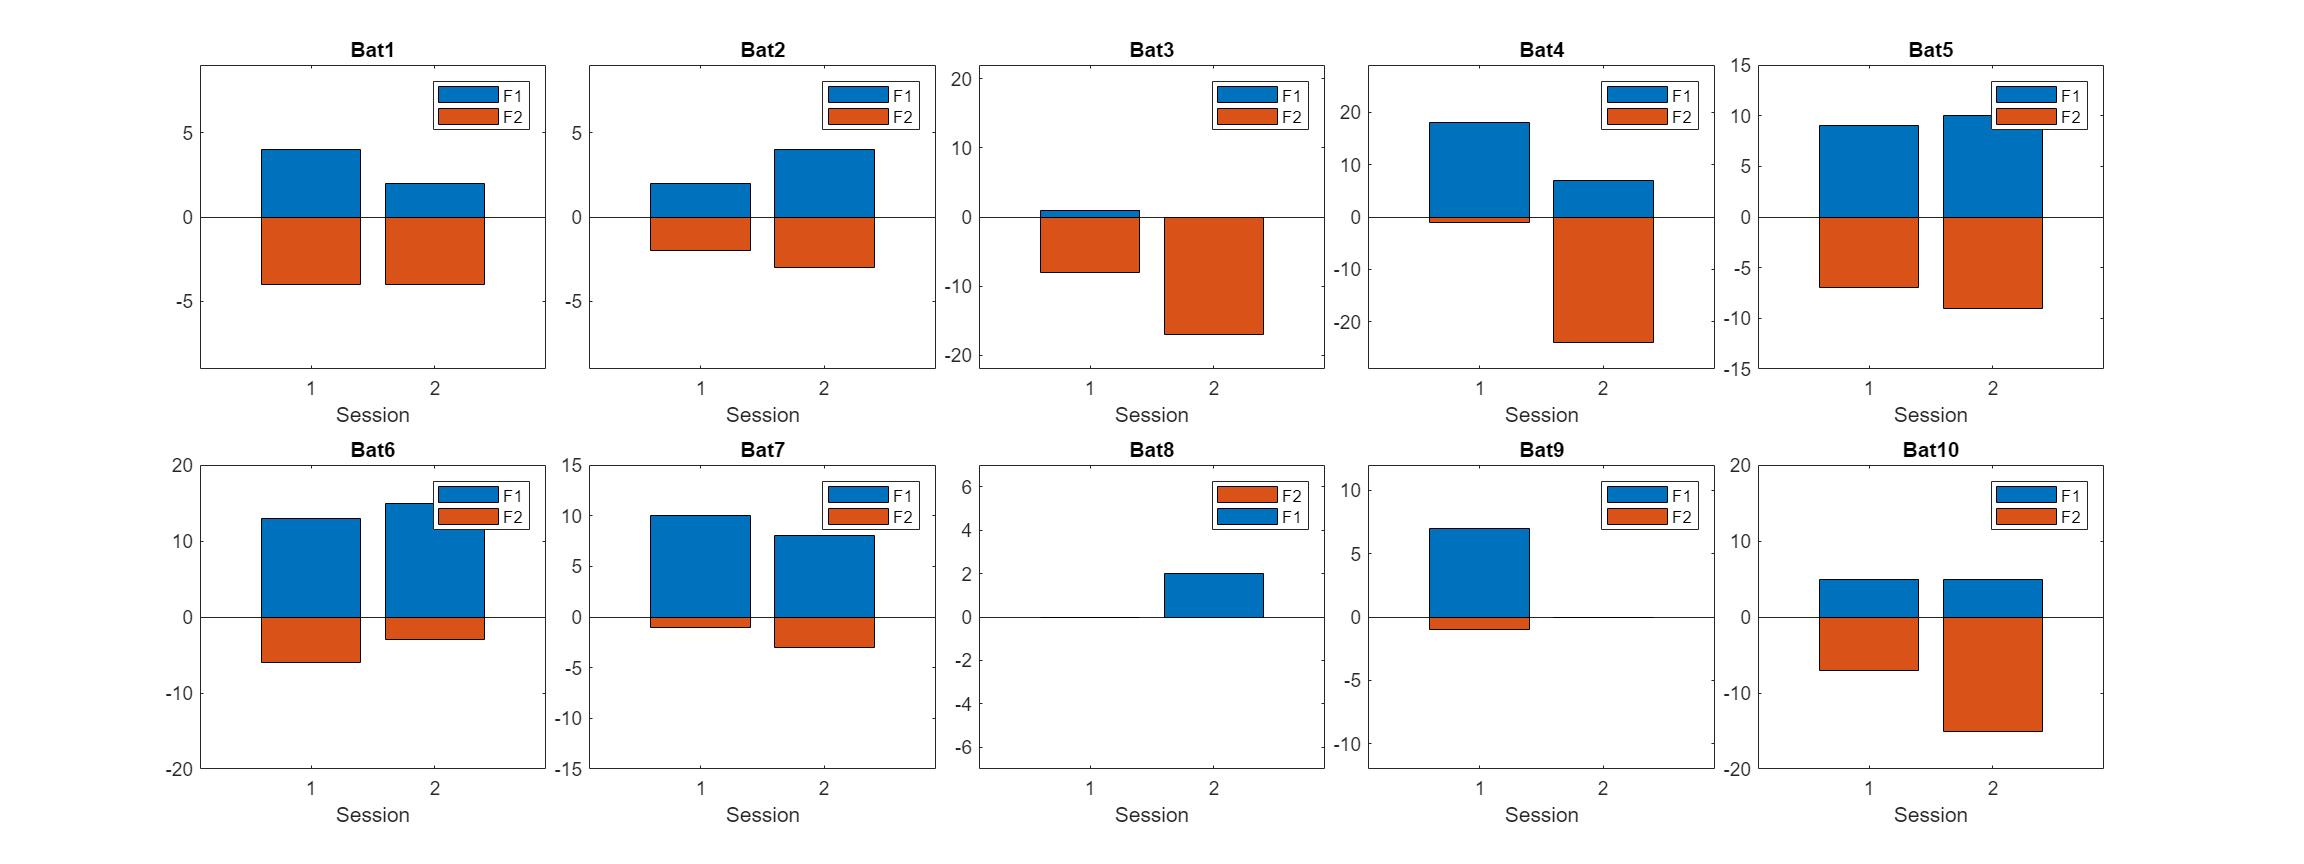

figure
set(gcf, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tiledlayout(2,5,"TileSpacing",'compact')
for bb = 1:n_tags

    fl_pref = zeros(n_session,n_feeder);
    for ss = 1:n_session
        for ff = 1:n_feeder
            feeder_pref(ss,ff) = size(reward(reward(:,1)==bb & reward(:,6)==ss & reward(:,2)==ff,:),1);
        end
    end
    max_cnt = max(max(feeder_pref));
    feeder_pref(:,2) = feeder_pref(:,2)*-1;
    nexttile
    bar(categorical(1:n_session),feeder_pref,'stacked')
    title(sprintf('Bat%s',num2str(bb)))
    xlabel('Session')
    ylabel('')
    legend({"F1","F2"})
    ylim([-1*(max_cnt+5),max_cnt+5])
end